%% reset legend
lg = {};
fig = figure;

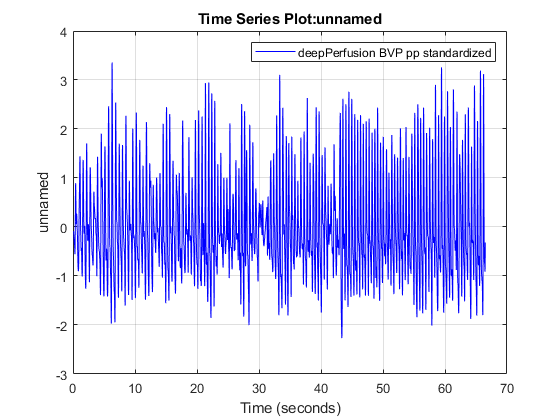

%% plot preprocessed BVP signal
idx = 7;

plot_curve = 6;

switch plot_curve
    case 1
        ts1 = timeseries(dp_data(idx).BVP_pp, dp_data(idx).TS_pp);
        lg{end+1} = 'deepPerfusion BVP pp';
        plot(ts1, 'r');
        hold on
        grid on
    case 2
        ts2 = timeseries(pos_data(idx).BVP_pp, pos_data(idx).TS_pp);
        lg{end+1} = 'POS BVP pp';
        plot(ts2, 'g');
        hold on
        grid on
    case 3
        ts3 = timeseries(gt_data(idx).BVP_pp, gt_data(idx).TS_pp);
        lg{end+1} = 'Ground truth BVP pp';
        plot(ts3, 'b');
        hold on
        grid on
    case 4
        ts4 = timeseries(gt_data(idx).BVP, gt_data(idx).TS);
        lg{end+1} = 'Ground truth BVP';
        plot(ts4, 'm');
        hold on
        grid on
    case 5
        ts5 = timeseries((pos_data(idx).BVP_pp - mean(pos_data(idx).BVP_pp))/std(pos_data(idx).BVP_pp), pos_data(idx).TS_pp);
        lg{end+1} = 'POS BVP pp standardized';
        plot(ts5, 'r');
        hold on
        grid on
    case 6
        ts6 = timeseries((dp_data(idx).BVP_pp - mean(dp_data(idx).BVP_pp))/std(dp_data(idx).BVP_pp), dp_data(idx).TS_pp);
        lg{end+1} = 'deepPerfusion BVP pp standardized';
        plot(ts6, 'b');
        hold on
        grid on
end
legend(lg)

% findpeaks(gt_data(i).BVP_pp, 'MinPeakDistance', ceil(resample_fs * 1/3), 'MinPeakProminence', 1)